addpath('Classes')
addpath('Simulink Models')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);

clear LMSPC_Int_x
clear LMSPC_PID_x

# Linear Moving Setpoint Controller (State Space Formulation) Class Developement Script

This script aids in the developement and documentation of the Lin_Mvng_Stpt_Cntr_SS class. 

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 

%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;
end 

if (~exist('LMSPC_Int_x', 'var'))

    LMSPC_Int_x = Lin_Mvng_Stpt_Cntr_SS(Lnrzed_EOMs, VDefs, 'SS Integral Controller x dimension')

end

LMSPC_Int_x =   Lin_Mvng_Stpt_Cntr_SS with properties:

          sys_mats: [1×1 struct]
      sim_response: []
     ctrl_type_dim: 'SS Integral Controller x dimension'
        stateVec_a: [5×1 sym]
    stateVec_a_dot: [5×1 sym]
       setpointVec: []



if (~exist('LMSPC_PID_x', 'var'))

    LMSPC_PID_x = Lin_Mvng_Stpt_Cntr_SS(Lnrzed_EOMs, VDefs, 'SS PID Controller x dimension')

end

LMSPC_PID_x =   Lin_Mvng_Stpt_Cntr_SS with properties:

          sys_mats: [1×1 struct]
      sim_response: []
     ctrl_type_dim: 'SS PID Controller x dimension'
        stateVec_a: [5×1 sym]
    stateVec_a_dot: [5×1 sym]
       setpointVec: [3×1 sym]


## Methodology

The feasibility of a setpoint controller for trajectory tracking is explored in this script. A traditional setpoint controller architecture is employed but the setpoint is not simple. The setpoint is chosen as the desired trajectory in x and y as functions of time. 

## Augmented System For State Space Representation of an Integral Controller

### Define Augmented State Vector


$$\tilde{x}_{1a} = [
 \int_0^t \!e_x\, \mathrm{d}t~x ~\dot{x} ~\beta~\dot{\beta}]^T


$$


Where $e_x$ is the error in the $x$ position of the ball relative to $x_s$, the setpoint,


$$e_x = x_s - x$$


### Get Matrices for Augmented Dynamics

The new dynamics are found by differentiating the augmented state vector:


$$\dot{\tilde{x}}_{1a}  = 

\left\lbrack \begin{array}{c}

e_x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

= 

\left\lbrack \begin{array}{c}

x_s - x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack$$


This produces a matrix equation with the following form:


$$\dot{\tilde{x}}_{1a} = A_{1a}\tilde{x}_{1a} + B_{1a}T_\beta + S_{1a}{x}_{s}$$


$A_{1a}$ is the $A_1$ matrix modified to contain the dynamics of the $\int_{0}^{t}e_xdt~$term. This term's dynamics are the error itself, $e_x$, so the augmentation is a simple one. 

A1a_Int = LMSPC_Int_x.sys_mats.Aa

$$A1a\_Int = \left[\begin{array}{ccccc} 0 & -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

$B_{1a}$ is the direct influence of the actuation torque on the system. Since the integral of the error is not a direct function of this signal, the augmented matrix recieves another zero element. 

B1a_Int = LMSPC_Int_x.sys_mats.Ba

$$B1a\_Int = \left[\begin{array}{c} 0\\ 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$

$S_{1a}$ is the matrix that tells how the setpoint $x_s$ enters into the dynamics. It essentially derives from the definition of the error term and partially determines the dynamics of the $\int_{0}^{t}e_xdt~$term. 

S1a_int = LMSPC_Int_x.sys_mats.S

$$S1a\_int = \left[\begin{array}{c} 1\\ 0\\ 0\\ 0\\ 0 \end{array}\right]$$

The final equations of motion are:


$$

\left\lbrack \begin{array}{c}

e_x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

=

\left\lbrack \begin{array}{ccccc}
0 & -1 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & -5.2170 & 0 & 4.0111 & 0\\
0 & 0 & 0 & 0 & 1\\
0 & 112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

 \int_0^t \!e_x\, \mathrm{d}t\\ x\\ \dot{x}\\ \beta\\ \dot{\beta}\\



\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{c}
0\\
0\\
-17.7268\\
0\\
383.5785
\end{array}\right\rbrack


T_{\beta }

+ 

\left\lbrack \begin{array}{c}
1\\
0\\
0\\
0\\
0
\end{array}\right\rbrack


x_s\\

$$


### Output Equation

%Our desired control output is the x state (want it to match as closely as possible to x_s
%for all times)
C1a_Int = LMSPC_Int_x.sys_mats.C

$$C1a\_Int = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0 \end{array}\right]$$

D1a_Int = LMSPC_Int_x.sys_mats.D

D1a_Int = 0


%This is for plotting x_s and x on the same scope
x_s_select_Int = LMSPC_Int_x.sys_mats.x_s_select

x_s_select_Int = 1

## Place the poles of the closed loop transfer function - Integral Controller


$$\frac{{X_s}(s)}{X(s)}  = C_{1a}(SI - (A_{1a} - B_{1a}K_1))^{-1}S_{1a} + D_{1a}$$


where the matrices all belong to the augmented state space system. The effect is to avoid having to choose an integral gain in an architecuture of the form


$$\frac{{X_s}(s)}{X(s)}  = \frac{C(s)P(s)}{1 + C(s)P(s)$$


where $C(s)$ is an integral controller, $\frac{K_i}{s}$, and $P(s)$ is the open loop plant


$$P(s) = \frac{T_{\beta}(s)}{X(s)} = C_1(SI - A_1)^{-1}B_1 + D_1$$
 

With the augmented system, we can simply use full state feedback to arbitrarily place the poles of the integral controller rather than having to use three dimensional root locus techniques in our choice of $K_i$. 

K_Int = place(double(A1a_Int),double(B1a_Int), [-10 -20 -30 -4 -5]); 

### Moving Setpoint Parameters

r_sim = .1; % radius of circular trajectory [m]
omega_sim =  2*pi/3; %angular frequency of circular trajectory 

des_traj_sym_Int_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t)

$$des\_traj\_sym\_Int\_x(t) = 0.1000\,\sin\left(2.0944\,t\right)$$

% des_traj_sym_Int_x = 0*VDefs.t;

### Overlay a fist order response so that the desired trajectory is smoothed out a bit

T = (2*pi/omega_sim)/5 %Time constant of the first order response that smooths out the trajectory

T = 0.6000

des_traj_sym_Int_x(VDefs.t) = (1 - exp(-(VDefs.t/T)))*des_traj_sym_Int_x

$$des\_traj\_sym\_Int\_x(t) = -0.1000\,\sin\left(2.0944\,t\right)\,\left({\mathrm{e}}^{-1.6667\,t}-1\right)$$

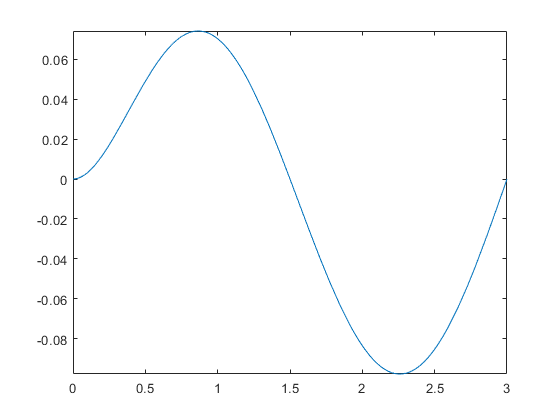

fplot(des_traj_sym_Int_x) 
xlim([0 2*pi/omega_sim]); 

## Simulate the Integral Controller

%Specify simulation time
tspan = [0 2*pi/omega_sim]*10;
%Specify initial conditions
xa_0 = [0 0 0 0 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system


LMSPC_Int_x.Run_Sim(des_traj_sym_Int_x, tspan, xa_0, K_Int);

simout_Int_x = LMSPC_Int_x.sim_response

simout_Int_x =   Simulink.SimulationOutput:

                      T: [10771x1 double] 
                   tout: [10771x1 double] 
                x_s_vec: [10771x1 double] 
                     xa: [10771x5 double] 
                      y: [10771x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Augmented System For State Space Representation of a PID Controller

### Define Augmented State Vector


$$\tilde{x}_{1a} = [
 \int_0^t \!e_x\, \mathrm{d}t ~ e_x ~ e_\dot{x} ~ \beta~\dot{\beta}]^T


$$



$$\dot{\tilde{x}}_{1a} = [
e_x ~e_\dot{x} ~ e_\ddot{x}  ~\beta~\dot{\beta}]^T$$


Where $e_\dot{x}$ is the error in the $x$ direction velocity,


$$e_\dot{x} = \dot{x}_s - \dot{x}$$


and $\(\int_{0}^{t} e_x \,\mathrm{d}t\)$ is the error in the integral of the $x$ position, 


$$ \int_0^t \!e_x\, \mathrm{d}t  ~=~  \int_0^t \!x_s\,   -  x\, \mathrm{d}t  ~=~  \int_0^t \!x_s\, \mathrm{d}t   ~-~ \int_0^t \!x\, \mathrm{d}t $$


### Get Matrices for Augmented Dynamics

The new dynamics are found by differentiating the augmented state vector:


$$\dot{\tilde{x}}_{1a}  = 

\left\lbrack \begin{array}{c}

e_x\\ e_{\dot{x}}\\ e_{\ddot{x}}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

= 

\left\lbrack \begin{array}{c}

x_s - x\\

\dot{x}_s - \dot{x}\\ 

\ddot{x}_s - \ddot{x}\\ 

\dot{\beta}\\ 

\ddot{\beta}\\



\end{array}\right\rbrack$$


stateVec1a_PID = LMSPC_PID_x.stateVec_a 

$$stateVec1a\_PID = \left[\begin{array}{c} e_{\mathrm{ix}}\\ e_{x}\\ e_{\dot{x}}\\ \beta \\ \dot{\beta } \end{array}\right]$$

This produces a matrix equation with the following form:


$$\dot{\tilde{x}}_{1a} = A_{1a}\tilde{x}_{1a} + B_{1a}T_\beta + S_{1a}{x}_{s}$$


### Get Matrices for Augmented Dynamics


$$\dot{\tilde{x}}_{1a} = A_{1a}\tilde{x}_{1a} + B_{1a}T_\beta + S_{1a}\tilde{x}_{1s}$$


Where $S_{1a}$ is the input matrix for the setpoint vector $\tilde{x}_{1s} = [x_s ~\dot{x}_s~\ddot{x}_s]$. $A_{1e}$ is the state coupling matrix for the augmented - error state vector $\tilde{x}_{1a}$ and $B_{1a}$ is the input matrix for torque $T_\beta$. 


stateVec1a_dot_PID = LMSPC_PID_x.stateVec_a_dot 

$$stateVec1a\_dot\_PID = \left[\begin{array}{c} e_{x}\\ e_{\dot{x}}\\ e_{\ddot{x}}\\ \dot{\beta }\\ \ddot{\beta } \end{array}\right]$$


A1a_PID = LMSPC_PID_x.sys_mats.Aa

$$A1a\_PID = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & -4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & -112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$


B1a_PID = LMSPC_PID_x.sys_mats.Ba

$$B1a\_PID = \left[\begin{array}{c} 0\\ 0\\ 17.7268\\ 0\\ 383.5785 \end{array}\right]$$


S1a_PID = LMSPC_PID_x.sys_mats.S

$$S1a\_PID = \left[\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 5.2170 & 0 & 1\\ 0 & 0 & 0\\ 112.8871 & 0 & 0 \end{array}\right]$$

The final equations of motion are:


$$

\left\lbrack \begin{array}{c}

e_x\\ e_{\dot{x}}\\ e_{\ddot{x}}\\ \dot{\beta}\\ \ddot{\beta}\\



\end{array}\right\rbrack

=

\left\lbrack \begin{array}{ccccc}
0 & 1 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & -5.2170 & 0 & -4.0111 & 0\\
0 & 0 & 0 & 0 & 1\\
0 & -112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

 \int_0^t \!e_x\, \mathrm{d}t\\ e_x\\ e_\dot{x}\\ \beta\\ \dot{\beta}\\



\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{c}
0\\
0\\
17.7268\\
0\\
383.5785
\end{array}\right\rbrack


T_{\beta }

+ 

\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
5.2170 & 0 & 1\\
0 & 0 & 0\\
112.8871 & 0 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}
x_s \\
{\dot{x} }_s \\
{\ddot{x} }_s 
\end{array}\right\rbrack

$$


### Output Equation

%Our desired control output is the x state (want it to match as closely as possible to x_s
%for all times). Given that x = x_s - e_x, C and D are:
C1a_PID = LMSPC_PID_x.sys_mats.C 

C1a_PID =      0    -1     0     0     0


D1a_PID = LMSPC_PID_x.sys_mats.D 

D1a_PID =      1     0     0



%x setpoint selector matrix (plotting in Simulink purposes)
x_s_select_PID = LMSPC_PID_x.sys_mats.x_s_select

x_s_select_PID =      1     0     0


### Find Integral and Derivatives of Trajectory

des_traj_sym_dot_Int_x(VDefs.t) = diff(des_traj_sym_Int_x(VDefs.t),VDefs.t)

$$des\_traj\_sym\_dot\_Int\_x(t) = 0.1667\,{\mathrm{e}}^{-1.6667\,t}\,\sin\left(2.0944\,t\right)-0.2094\,\cos\left(2.0944\,t\right)\,\left({\mathrm{e}}^{-1.6667\,t}-1\right)$$

des_traj_sym_ddot_Int_x(VDefs.t) = diff(des_traj_sym_Int_x(VDefs.t),VDefs.t,2)

$$des\_traj\_sym\_ddot\_Int\_x(t) = 0.6981\,{\mathrm{e}}^{-1.6667\,t}\,\cos\left(2.0944\,t\right)-0.2778\,{\mathrm{e}}^{-1.6667\,t}\,\sin\left(2.0944\,t\right)+0.4386\,\sin\left(2.0944\,t\right)\,\left({\mathrm{e}}^{-1.6667\,t}-1\right)$$


%Create function handles from the desired trajectory information
des_traj_sym_PID_x = [des_traj_sym_Int_x;des_traj_sym_dot_Int_x;des_traj_sym_ddot_Int_x]

$$des\_traj\_sym\_PID\_x(t) = \left[\begin{array}{c} -0.1000\,\sin\left(2.0944\,t\right)\,\left({\mathrm{e}}^{-1.6667\,t}-1\right)\\ 0.1667\,{\mathrm{e}}^{-1.6667\,t}\,\sin\left(2.0944\,t\right)-0.2094\,\cos\left(2.0944\,t\right)\,\left({\mathrm{e}}^{-1.6667\,t}-1\right)\\ 0.6981\,{\mathrm{e}}^{-1.6667\,t}\,\cos\left(2.0944\,t\right)-0.2778\,{\mathrm{e}}^{-1.6667\,t}\,\sin\left(2.0944\,t\right)+0.4386\,\sin\left(2.0944\,t\right)\,\left({\mathrm{e}}^{-1.6667\,t}-1\right) \end{array}\right]$$

### Place the poles of the closed loop transfer function 


$$\frac{{X_s}(s)}{X(s)}  = C_{1a}(SI - (A_{1a} - B_{1a}K_1))^{-1}S_{1a} + D_{1a}$$


where the matrices all belong to the augmented state space system. The effect is to avoid having to choose PID gains in an architecuture of the form


$$\frac{{X_s}(s)}{X(s)}  = \frac{C(s)P(s)}{1 + C(s)P(s)$$


where $C(s)$ is a PID controller and $P(s)$ is the open loop plant


$$P(s) = \frac{T_{\beta}(s)}{X(s)} = C_1(SI - A_1)^{-1}B_1$$
 

At the very least, this provides for bounded input - bounded output stability. However, this tells us nothing directly about the tracking performance of the controller. With the augmented system, we can simply use full state feedback to arbitrarily place the poles of the PID controller rather than having to use three dimensional root locus techniques in our choice of $K_i, ~K_p, ~and~K_d$. 

K_PID = place(double(A1a_PID),double(B1a_PID), [-10 -20 -30 -4 -5])

K_PID =   -44.6463  -28.5703   -6.6566    5.8034    0.4875


% K_PID = place(double(A1a_PID),double(B1a_PID), [-10 -20 -30 -4 -5]/3)

% K_PID = [-10 -87.2359 -46.5577 87.0181 12.6186]; %Testing Zach's gains (with my integral gain in there)

% Q_e_ix = 1/5^2;
% Q_e_x = 1/.005^2;
% Q_e_xd = 1/.010^2; 
% Q_b = 1/deg2rad(25)^2; 
% Q_bd = 1/omega_sim^2;
% 
% Q = [Q_e_ix 0 0 0 0; 
%      0 Q_e_x 0 0 0;
%      0 0 Q_e_xd 0 0;
%      0 0 0 Q_b 0;
%      0 0 0 0 Q_bd];
% 
% R = 1/73^2; %2
% 
% [K_PID,S,e] = lqr(double(A1a_PID), double(B1a_PID), Q,R);
% K_PID

## Simulate the PID Controller

%Specify simulation time
tspan = [0 2*pi/omega_sim]*10;
% tspan = [0 2] %For checking Zach's regulator gains
%Specify initial conditions
xa_0 = [0 0 0 0 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system
% xa_0 = [0 -.2 0 0 0]; %Checking Zach's regulator gains

LMSPC_PID_x.Run_Sim(des_traj_sym_PID_x, tspan, xa_0, K_PID);

simout_PID_x = LMSPC_PID_x.sim_response

simout_PID_x =   Simulink.SimulationOutput:

                      T: [7049x1 double] 
                   tout: [7049x1 double] 
                x_s_vec: [7049x3 double] 
                     xa: [7049x5 double] 
                      y: [7049x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Compare the Responses

### Raw Simulation Data Plotted

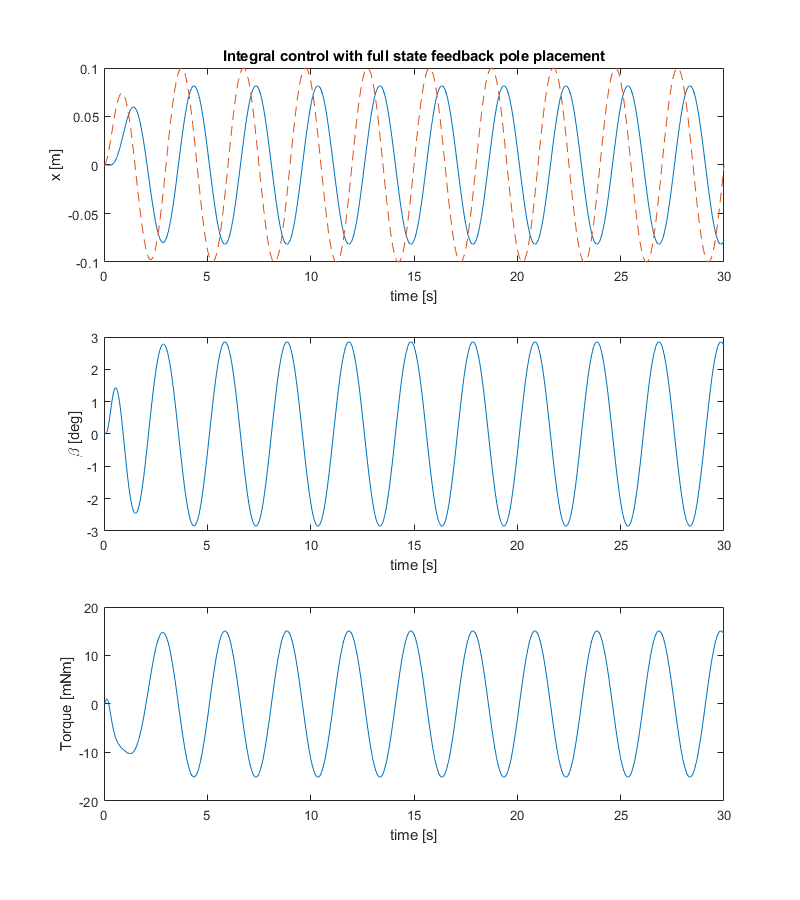

%Plot the integral controller results

Int_fig = LMSPC_Int_x.plot_results('Integral control with full state feedback pole placement');

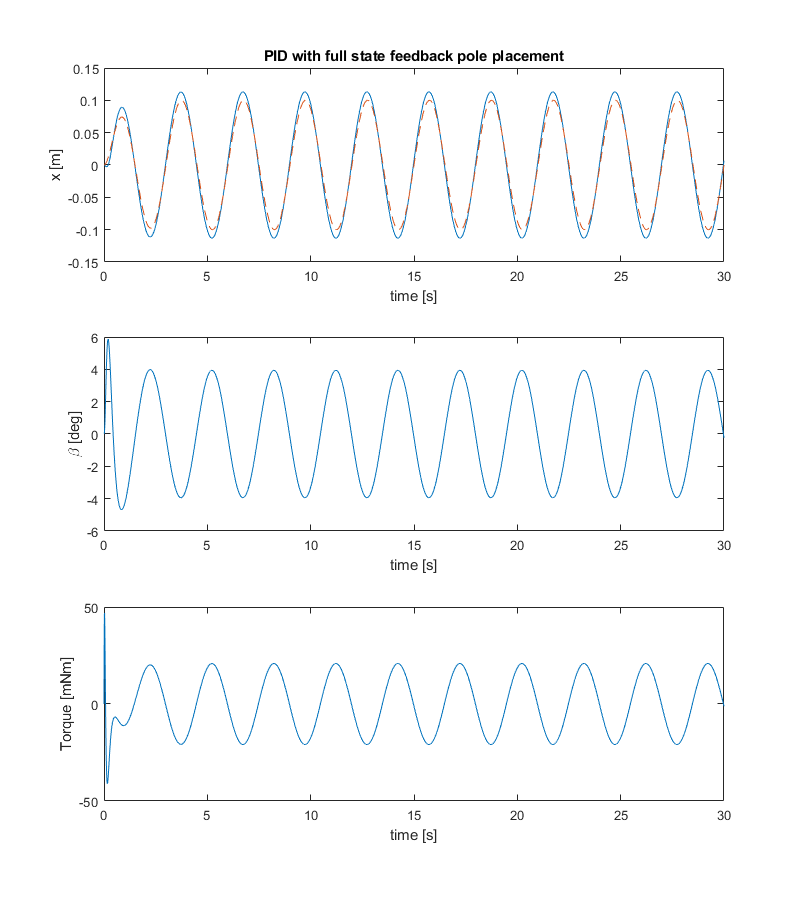




% %Plot the PID controller results
PID_fig = LMSPC_PID_x.plot_results('PID with full state feedback pole placement');

% Int_fig.Name = 'name1'